# Tarea 2

## Computación Aplicada

#### Regresión Lineal y Ajuste de Curvas

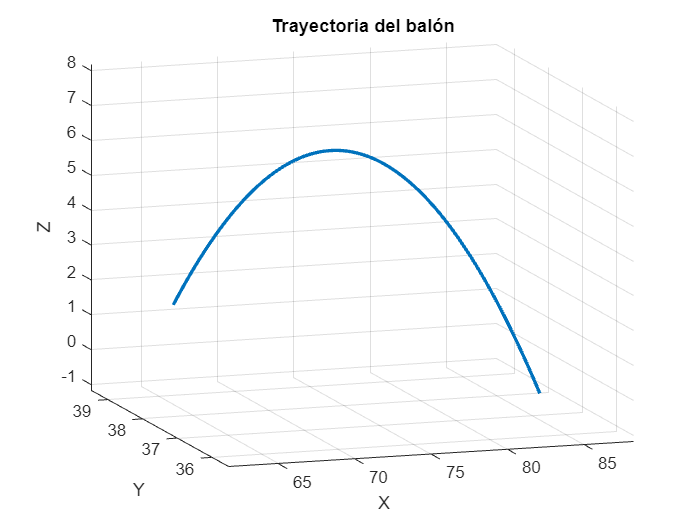

clear all
close all
clc

% Cargar los datos del archivo Excel Data3.xlsx
data = readtable('D:\Users\stccr\Desktop\Trabajos\M 1er\Computación Aplicada\Tarea 2\Data3.xlsx');

% Extraer los datos de posición X, Y y Z y el tiempo t
x = data.X;
y = data.Y;
z = data.Z;
t = data.time;

% Graficar la trayectoria del balón
figure(1)
plot3(x, y, z, 'LineWidth', 2);
grid on;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Trayectoria del balón');


% Ajustar una parábola a los datos de posición Z en función del tiempo t
Pz = polyfit(t,z,2);

% Extraer el coeficiente A (aceleración debida a la gravedad) de la parábola
A = -2*Pz(1);

% Calcular la velocidad inicial del balón
% Primero, calcular la velocidad en la dirección X y Y con la posición y el
% tiempo
Py=polyfit(t,y,1);
Px=polyfit(t,x,1);

V=sqrt(Px(1)^2+Py(1)^2+Pz(2)^2);

fprintf('La ecuación que describe la parábola en el eje Z está dada por:')

La ecuación que describe la parábola en el eje Z está dada por:

fprintf('Pz= %.3f t^2 + %.3f t + %.3f \n',Pz(1),Pz(2),Pz(3))

Pz= -2.500 t^2 + 8.000 t + -0.000 


%

fprintf('La aceleración de la gravedad en el planeta es %.2f [m/s^2]\n', A);

La aceleración de la gravedad en el planeta es 5.00 [m/s^2]


%

fprintf('La ecuación que describe el desplazamiento en y está dado por:')

La ecuación que describe el desplazamiento en y está dado por:

fprintf('Py= %.3f t + %.3f',Py(1),Py(2))

Py= 0.926 t + 36.120

%

fprintf('La ecuación que describe el desplazamiento en x está dado por:')

La ecuación que describe el desplazamiento en x está dado por:

fprintf('Px= %.3f t + %.3f \n',Px(1),Px(2))

Px= -5.928 t + 83.520 


%

fprintf('De las ecuaciones de posición en los 3 ejes, se obtiene el vector velocidad inicial:')

De las ecuaciones de posición en los 3 ejes, se obtiene el vector velocidad inicial:

fprintf('V= %.3f i + %.3f j + %.3f k [m/s]\n',Px(1),Py(1),Pz(2))

V= -5.928 i + 0.926 j + 8.000 k [m/s]


%

fprintf('El valor absoluto de la velocidad inicial es:')

El valor absoluto de la velocidad inicial es:

fprintf('|V|= %.3f [m/s]',V)

|V|= 10.000 [m/s]